In primis capiamo quali matrici devo convertire

changeInertiaMat=true;
changeVelocityTerms=false; %per calcolarla devi avere M(p), quindi devi avere gia trasformato M
changeGravitationalTerms=false;
ChangeAppliedTorque=false;

%syms m1 m2 m3 dc3 q3 I3 q1 q2 l3
%q=[q1;q2;q3];
%n=3;
%M=[m1+m2+m3 0 m3*dc3*cos(q3);0 m2+m3 -m3*dc3*sin(q3); m3*dc3*cos(q3) -m3*dc3*sin(q3) I3+m3*dc3^2];


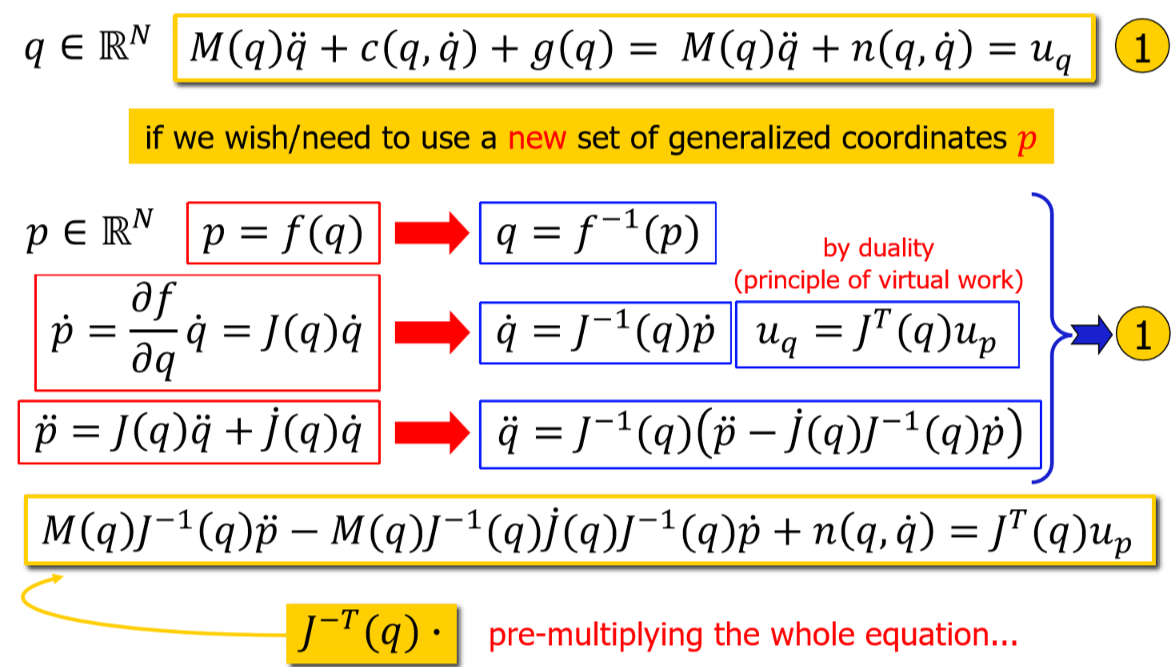

define $p=f(q)$

%p_of_q=[q2+l3*cos(q3);q1+l3*sin(q3);q3] %p=f(q) deve essere una funzione di q
p_of_q=[q1;q1+q2;q1+q2+q3;q1+q2+q3+q4]

$$p\_of\_q = \left(\begin{array}{c} q_{1}\\ q_{1}+q_{2}\\ q_{1}+q_{2}+q_{3}\\ q_{1}+q_{2}+q_{3}+q_{4} \end{array}\right)$$

if(size(p_of_q)~=n)
    error('Le dimensioni del cambio di coordinate e del sistema non combaciano')
end

Get the reverse change of coordinates $q=f^{-1}(p)$

**ATTENZIONE DEVI CONFIGURARE A MANO IL SISTEMA**

q_of_p=sym('q_of_p',[n,1]);
p=sym('p',[n,1]);


eq1 = p(1,1) == p_of_q(1,1);
eq2 = p(2,1) == p_of_q(2,1);
eq3 = p(3,1) == p_of_q(3,1);
eq4 = p(4,1) == p_of_q(4,1);

% Risolvi le equazioni
%[q_of_p(1,1), q_of_p(2,1), q_of_p(3,1)] = solve([eq1, eq2, eq3], [q1, q2, q3]);
[q_of_p(1,1), q_of_p(2,1), q_of_p(3,1),q_of_p(4,1)] = solve([eq1, eq2, eq3,eq4], [q1, q2, q3,q4]);


q_of_p

$$q\_of\_p = \left(\begin{array}{c} p_{1}\\ p_{2}-p_{1}\\ p_{3}-p_{2}\\ p_{4}-p_{3} \end{array}\right)$$

Now let's compute the new model:

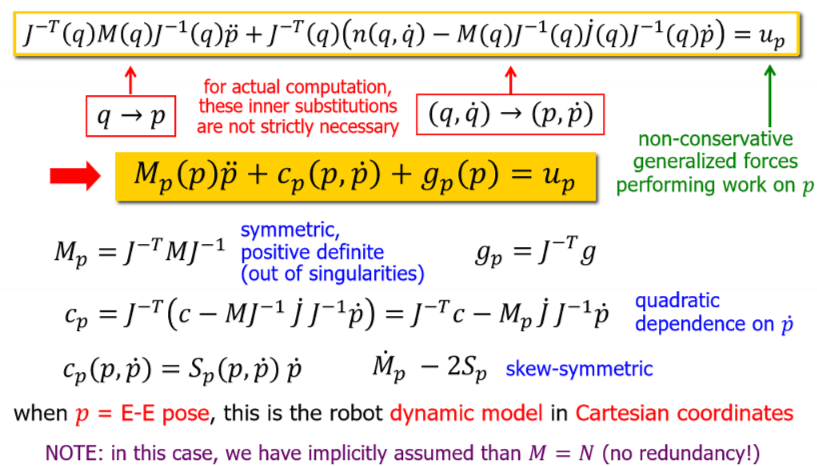

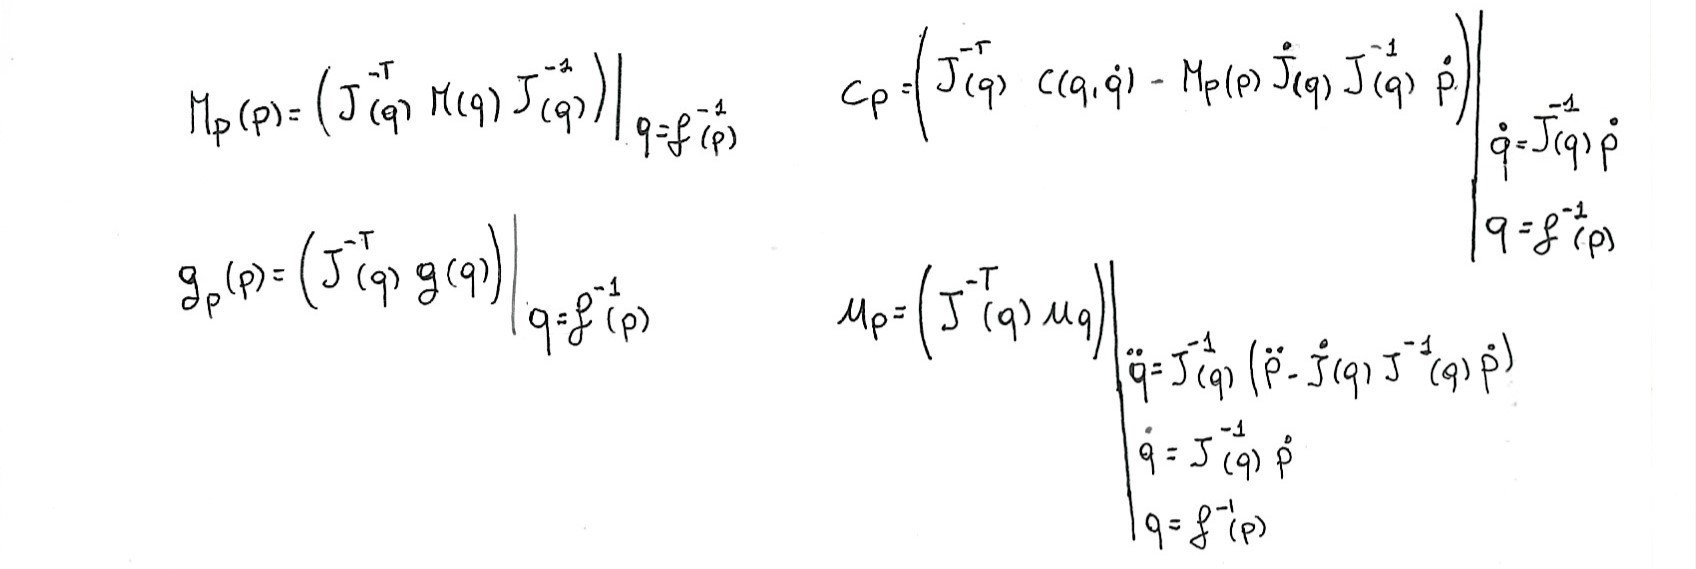

J_of_q=jacobian(p_of_q,q)

$$J\_of\_q = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 1 & 1 & 0 & 0\\ 1 & 1 & 1 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

inv_J_of_q=inv(J_of_q)

$$inv\_J\_of\_q = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ -1 & 1 & 0 & 0\\ 0 & -1 & 1 & 0\\ 0 & 0 & -1 & 1 \end{array}\right)$$

Jdot_of_q=0;
for i=1:n
    Jdot_of_q=Jdot_of_q+diff(J_of_q,q(i,1))*qd(i,1);
end
Jdot_of_q

$$Jdot\_of\_q = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$



if(changeInertiaMat)
    new_M_of_p=simplify((transpose(inv_J_of_q)*M*inv_J_of_q))
    disp('This needs to be evaluated using q=f^{-1}(p)')
    %now substitute the q using q_of_p
    for i=1:n
        new_M_of_p=subs(new_M_of_p,q(i,1),q_of_p(i,1));
    end
    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp('After this substitution we get:')
    new_M_of_p

    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp("let's do it using a completely symbolical M");
    MM=sym('mm',[n,n]);
    for k=1:n
        for i=1:n
            if(i>=k)
                nomeVariabile = ['mm' num2str(k) num2str(i)];
                assignin('base', nomeVariabile,MM(i,k));
            else
                MM(i,k)=MM(k,i);
            end
    
        end
    end
    MM
    new_MM_of_p=simplify((transpose(inv_J_of_q)*MM*inv_J_of_q))
    disp('This needs tobe evaluated using q=f^{-1}(p)')

end

This needs to be evaluated using q=f^{-1}(p)


------------------------------------------------


After this substitution we get:


------------------------------------------------


let's do it using a completely symbolical M


$$MM = \left(\begin{array}{cccc} {\mathrm{mm}}_{1,1} & {\mathrm{mm}}_{2,1} & {\mathrm{mm}}_{3,1} & {\mathrm{mm}}_{4,1}\\ {\mathrm{mm}}_{2,1} & {\mathrm{mm}}_{2,2} & {\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{4,2}\\ {\mathrm{mm}}_{3,1} & {\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{3,3} & {\mathrm{mm}}_{4,3}\\ {\mathrm{mm}}_{4,1} & {\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{4,4} \end{array}\right)$$

$$new\_MM\_of\_p = \left(\begin{array}{cccc} {\mathrm{mm}}_{1,1}-2\,{\mathrm{mm}}_{2,1}+{\mathrm{mm}}_{2,2} & {\mathrm{mm}}_{2,1}-{\mathrm{mm}}_{2,2}-{\mathrm{mm}}_{3,1}+{\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{3,1}-{\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{4,1}+{\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{4,1}-{\mathrm{mm}}_{4,2}\\ {\mathrm{mm}}_{2,1}-{\mathrm{mm}}_{2,2}-{\mathrm{mm}}_{3,1}+{\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{2,2}-2\,{\mathrm{mm}}_{3,2}+{\mathrm{mm}}_{3,3} & {\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{3,3}-{\mathrm{mm}}_{4,2}+{\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{4,2}-{\mathrm{mm}}_{4,3}\\ {\mathrm{mm}}_{3,1}-{\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{4,1}+{\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{3,3}-{\mathrm{mm}}_{4,2}+{\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{3,3}-2\,{\mathrm{mm}}_{4,3}+{\mathrm{mm}}_{4,4} & {\mathrm{mm}}_{4,3}-{\mathrm{mm}}_{4,4}\\ {\mathrm{mm}}_{4,1}-{\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{4,2}-{\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{4,3}-{\mathrm{mm}}_{4,4} & {\mathrm{mm}}_{4,4} \end{array}\right)$$

This needs tobe evaluated using q=f^{-1}(p)


We need to verify them with exercises:

if(changeVelocityTerms)
    qd=sym('qd',[n,1])
    %ci serve solo per prendere le variabili e fare le sostituzioni
    pd=sym('pd',[n,1]); 
    
    %Jdot_of_q
    
    qd_of_p=inv_J_of_q*pd

    c
    new_c_of_p_pd = simplify(    (transpose(inv_J_of_q)*c -new_M_of_p*Jdot_of_q*inv_J_of_q*pd)    )

    disp('This needs to be evaluated using q=f^{-1}(p) and qd=J^{-1}(q)*pd')
    %now substitute the q using q_of_p
    for i=1:n
        new_c_of_p_pd=subs(new_c_of_p_pd,[q(i,1),qd(i,1)],[q_of_p(i,1),qd_of_p(i,1)]);
    end
    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp('After this substitution we get:')
    new_c_of_p_pd

    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp("let's do it using a completely symbolical c");
    cc=sym('cc',[n,1])
    new_cc_of_p= simplify(    (transpose(inv_J_of_q)*cc-new_MM_of_p*Jdot_of_q*inv_J_of_q*pd)    )
    disp('This needs tobe evaluated using q=f^{-1}(p) and qd=J^{-1}(q)*pd')

end

Gravity terms

if(changeGravitationalTerms)
    gravity_terms
    new_gravity_terms_of_p=simplify( traspose(inv_J_of_q)*gravity_terms) 

    disp('This needs to be evaluated using q=f^{-1}(p)')
    %now substitute the q using q_of_p
    for i=1:n
        new_gravity_terms_of_p=subs(new_gravity_terms_of_p,q(i,1),q_of_p(i,1));
    end
    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp('After this substitution we get:')
    new_gravity_terms_of_p

    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp("let's do it using a completely symbolical gravity_terms");
    gg=sym('gg',[n,1])
    new_gg_of_p= simplify( traspose(inv_J_of_q)*gg) 
    disp('This needs tobe evaluated using q=f^{-1}(p)')
end

Non conservative torques

if(ChangeAppliedTorque)
    pdd=sym('pdd',[n,1]);
    pd=sym('pd',[n,1]); 
    %it uses qd qdd se non ci sono mettili a 0
    qd=sym('qd',[n,1])
    qdd=sym('qdd',[n,1])
    %questi ci servono solo per prendere le variabili e fare le
    %sostituzioni


    qdd_of_p=inv_J_of_q(pdd-Jdot_of_q*inv_J_of_q*pd)

    %externalTorque_of_q= %to be defined
    new_externalTorque_of_p=simplify( traspose(inv_J_of_q)*gravity_terms) 

    disp('This needs to be evaluated using q=f^{-1}(p) qd=J^{-1}(q)*pd qdd=J^{-1}(q)(pdd-J_dot(q)J^{-1}pd ')
    %now substitute the q using q_of_p
    for i=1:n
        new_externalTorque_of_p=subs(new_externalTorque_of_p,[q(i,1),qd(i,1),qdd(i,1)],[q_of_p(i,1),qd_of_p(i,1),qdd_of_p(i,1)]);
    end
    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp('After this substitution we get:')
    new_externalTorque_of_p

    disp(' ');disp(' ');
    disp('------------------------------------------------');
    disp("let's do it using a completely symbolical gravity_terms");
    uu=sym('uu',[n,1])
    new_uu_of_p= simplify( traspose(inv_J_of_q)*uu) 
    disp('This needs tobe evaluated using q=f^{-1}(p) qd=J^{-1}(q)*pd  qdd=J^{-1}(q)(pdd-J_dot(q)J^{-1}pd ')
end